State Definition

[p0, p1, p2] = deal(0.2,0.35,0.45);
[alpha1,beta1] = deal(1.5,0.5);
[alpha2,beta2] = deal(3.0,2.0);
psi0 = [1 0 0];
psi1 = [sin(alpha1)*cos(beta1) sin(alpha1)*sin(beta1) cos(alpha1)];
psi2 = [sin(alpha2)*cos(beta2) sin(alpha2)*sin(beta2) cos(alpha2)];
RHO{1} = psi0'*psi0;
RHO{2} = psi1'*psi1;
RHO{3} = psi2'*psi2;

Paper's guessing probability calculation & Plotting

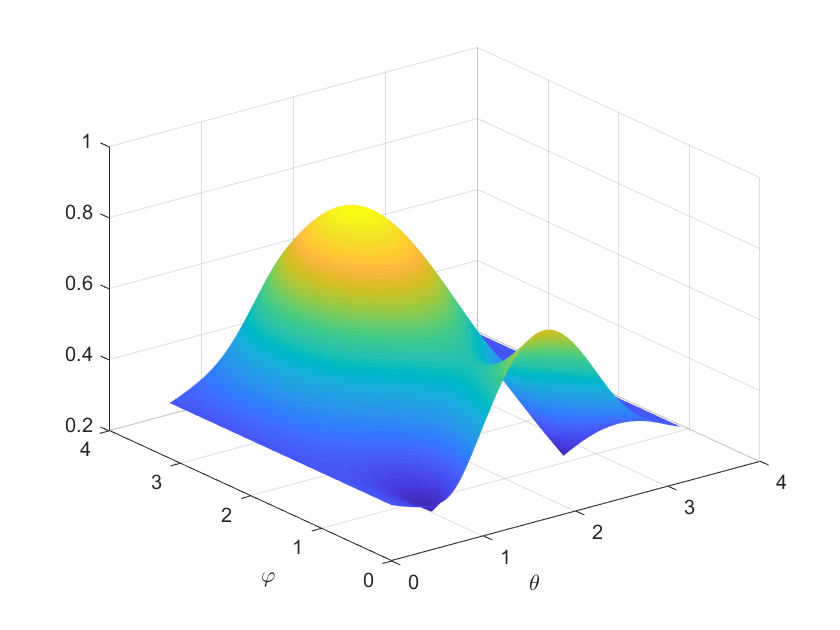


[THETA,PHI] = meshgrid(0:0.001:pi,0:0.001:pi);

g1 = cos(alpha1)*cos(THETA)+sin(alpha1)*sin(THETA).*cos(beta1-PHI);
g2 = cos(alpha2)*cos(THETA)+sin(alpha2)*sin(THETA).*cos(beta2-PHI);
h = (p1*(1-g1.^2)+p2*(1-g2.^2)).^2-4*p1*p2*(psi1*psi2.'-g1.*g2).^2;
f = p0*sin(THETA).^2.*cos(PHI).^2+ 0.5*(p1*(1-g1.^2)+p2*(1-g2.^2) +sqrt(h));
fig = surf(THETA,PHI,f,'LineStyle','none');
xlabel(['$\theta$'],'interpreter','latex')
ylabel('$\varphi$','interpreter','latex')
saveas(fig,'3Pure_LI_Ensemble.png');

Pguess_on_paper = max(max(f))

Pguess_on_paper = 0.8725

[phiopt,thetaopt]=find(Pguess_on_paper==f)

phiopt = 2387

thetaopt = 1451

Actual $P_{guess}$ from SDP.

Pguess = MinErrorDiscrimination([p0 p1 p2],RHO)

Pguess = 0.8725

Special Case

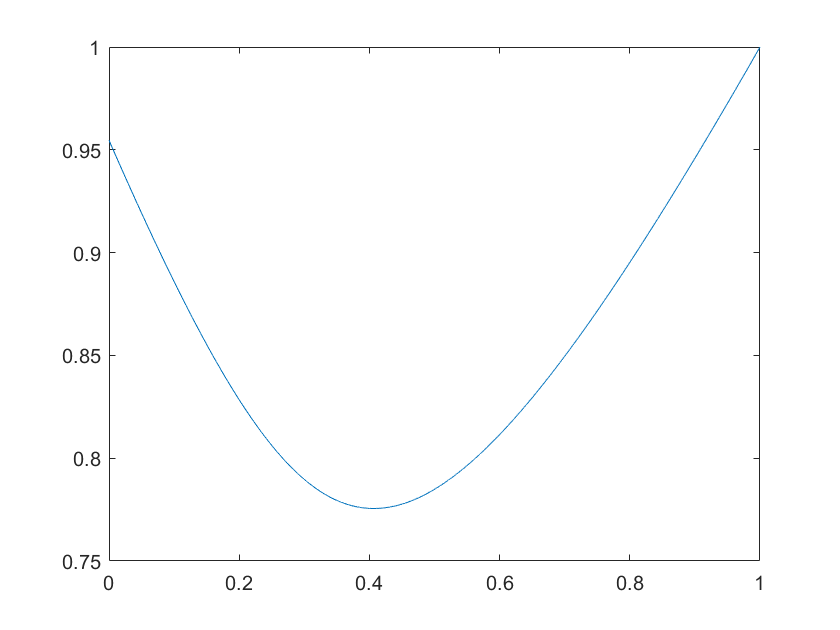

p0 = 0:0.0001:1;
phi = 0:0.01:pi;
alpha = 1.0;
beta = 0.5;
[P0,phi] = meshgrid(p0,phi);
f0 = P0.*cos(phi).^2 + (1-P0)/2.*(cos(alpha)+sin(alpha).*abs(sin(beta-phi))).^2;
mf0 = max(f0);
fig2 = plot(p0,mf0);
saveas(fig2,'Prior_Pg_graph.png');